# MACM 203 Assignment 2

## Preamble

In this question, we consider random, symmetric, sparse, positive definite matrices of size $n\times n$ defines as follows:

density = 0.1;

A = sprandsym(n, density);

A = A + diag(sum(abs(A'))) + density*speye(n);

b = ones(n,1);

We consider three methods for solving $A\;x=b$ in Matlab:

    Method (1): x1 = inv(A) * b;

    Method (2): x2 = A \ b;

    Method (3): x3 = pcg(A, b, tol, max_iterations);

For Method (3) we set TOLD=1e-4 and max_iterations=10000.

## Question.

Consider values of $n$ ranging from $n=100$ to $n=1000$, with increments of 100. Use the construction a:b:c to generate this range of values of $n$ and use a for-loop to iterate through this range of values of $n$.

For each value of $n$, generate thirty $n\times n$ matrices A and one right-hand side vector b=ones(n,1).

clearvars,clc
% For each value of n generate 30 nxn matrices A and 
% one RHS vector b=ones(n,1)
density = 0.1;
for n = 100:100:1000
    b = ones(n,1);
    for m = 1:30
        A = sprandsym(n,density);
        A = A + diag(sum(abs(A'))) + density*speye(n);
        %b = ones(n,1);
    end
end

## Part A: Average run times

We now solve $A\;x=b$ using Methods (1), (2) and (3) for each of the 30 matrices and record the average time for each method. Record the time using the tic and toc commands. Do not include the time to construct matrices $A$ and $b$ in your timing. For each $n$, print the average time of solving the systems via Methods (1), (2) and (3).

clearvars,clc

avg_times_method1 = [];
avg_times_method2 = [];
avg_times_method3 = [];

density = 0.1;
tol = 1e-4;
max_iterations = 10000;

nvals = 100:100:1000;

for n = nvals
    time_method1 = 0;
    time_method2 = 0;
    time_method3 = 0;
    b = ones(n,1);
    for m = 1:30
        A = sprandsym(n,density);
        A = A + diag(sum(abs(A'))) + density*speye(n);

        % Method 1
        tic;
        x1 = inv(A)*b;
        time_method1 = time_method1 + toc;

        % Method 2
        tic;
        x2 = A\b;
        time_method2 = time_method2 + toc;

        % Method 3
        tic;
        [x3,flag] = pcg(A, b, tol, max_iterations);
        time_method3 = time_method3 + toc;
    end
    % For Part B
    % Calculate the average time for each method
    avg_time_method1 = time_method1 / 30;
    avg_time_method2 = time_method2 / 30;
    avg_time_method3 = time_method3 / 30;
    % Store the average time for each method
    avg_times_method1 = [avg_times_method1, avg_time_method1];
    avg_times_method2 = [avg_times_method2, avg_time_method2];
    avg_times_method3 = [avg_times_method3, avg_time_method3];
end

## Part B: Plotting

Plot the average time to solve the system vs $n$ for each of the three methods. Plot the three graphs in the same figure using the semilogy command. Use red, blue and black lines for the three graphs, and provide a legend for the figure using Matlab's legend() command. To give a title and labels to the axes, use title, xlabel, ylabel. Take care to ensure that the legend does not obscure key data in your plots.

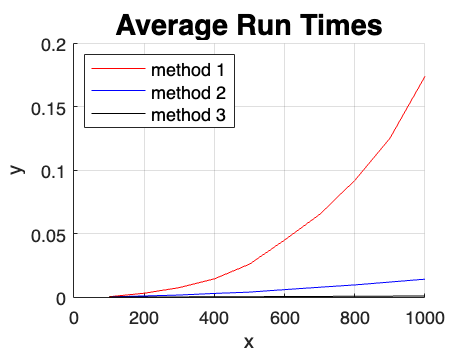

clf;
% plot(nvals,avg_times_method1);
% plot(nvals,avg_times_method2);
% plot(nvals,avg_times_method3);
hold on;
semilogy(nvals,avg_times_method1,'-r')
semilogy(nvals,avg_times_method2,'-b')
semilogy(nvals,avg_times_method3,'-k')
hold off;
title('Average Run Times','FontSize',16);
xlabel('x');
ylabel('y');
legend('method 1','method 2','method 3','Location','northwest','FontSize',10)
grid on;

## Part C: Discussion

Rank the 3 methods by speed for large $n$. Can you explain the result?

    In order from slowest to fastest is:

        (1) Method 1: x = inv(A)*b

        (2) Method 2: x = A\b

        (3) Method 3: x = pcg(A, b, tol, max_iterations)

Method 1:

    This is a direct method involves solving the matrix inverse by solving a system of linear equations for each column of the identity matrix, which can be computationally expensive for large matrices. This is essentially a brute force method, which is why it is the slowest.

Method 2:

    This method takes advantage of the sparsity, so it is faster than method 1. 

Method 3:

    This is an iterative method that takes advantage of the zero structure of the sparse matrix. It is not always faster, but in this case it is. The pcg method estimates the matrix until the residues are within the tolerance specified. 